# 例1.1（配列表現）

動作確認： MATLAB R2017a

## (a) グレースケール画像

fprintf('(a) グレースケール画像\n')

(a) グレースケール画像


V = imread('cameraman.tif');
fprintf('配列次元： D = %d\n',ndims(V))

配列次元： D = 2


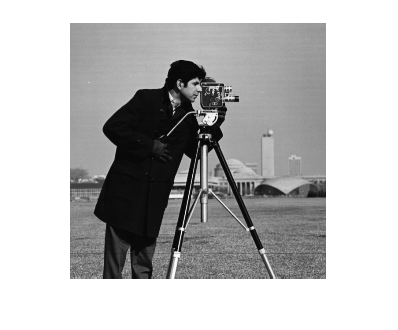

imshow(V)

## (b) RGB画像

fprintf('(b) RGB画像\n')

(b) RGB画像


V = imread('peppers.png');
fprintf('配列次元： D = %d\n',ndims(V))

配列次元： D = 3


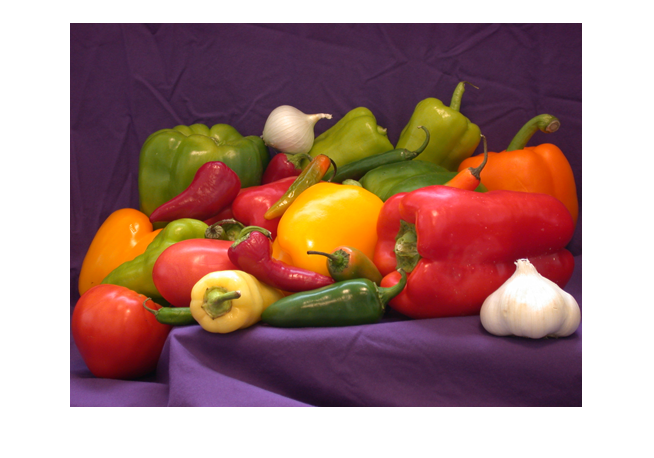

imshow(V)

## (c) 動画像

fprintf('(c) RGB動画像\n')

(c) RGB動画像


vrObj = VideoReader('shuttle.avi');
V = zeros(vrObj.Height,vrObj.Width,3,2,'uint8');
V(:,:,:,1) = readFrame(vrObj);
V(:,:,:,2) = readFrame(vrObj);
fprintf('配列次元： D = %d\n',ndims(V))

配列次元： D = 4


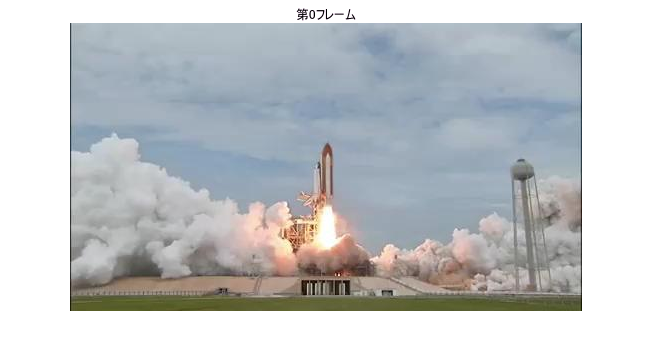

imshow(V(:,:,:,1))
title('第0フレーム')

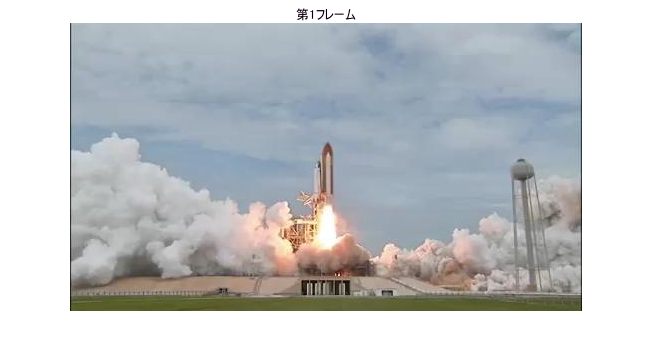

imshow(V(:,:,:,2))
title('第1フレーム')

## (d) ボリュームデーデータ

fprintf('(d) ボリュームデータ\n')

(d) ボリュームデータ


load mri
V = squeeze(D);
fprintf('配列次元： D = %d\n',ndims(V))

配列次元： D = 3


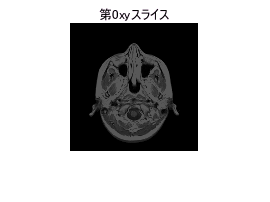

imshow(V(:,:,1))
title('第0xyスライス')

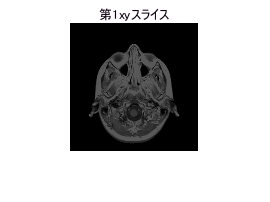

imshow(V(:,:,2))
title('第1xyスライス')